clear
close all

load VISPORC.mat

save MPnecc.mat newdirec measurement info measdir measurements
clear
load MPnecc.mat

init = 0;
sens_order = [1, 2, 3, 4, 5];

allopt.fig = figure(1);
allopt.stsize = 10

allopt = struct with fields:
       fig: [1×1 Figure]
    stsize: 10


allopt.MTC = 'r o';
allopt.OP1C = 'b o';
allopt.OP2C = 'k o';
allopt.OP3C = 'm o';
allopt.xmax = 0;
allopt.ymax = 0;
allopt.i =  0;
sens_order = [1, 2, 4, 5, 3];
rets = []


rets =

     []



measurement = measurements{1,2}

measurement = 35×4 cell array
    {'5'}    {'0' }    {'init'              }    {'5_0__init.txt'               }
    {'5'}    {'1' }    {'fist'              }    {'5_1__fist.txt'               }
    {'5'}    {'2' }    {'1_oppositio'       }    {'5_2__1_oppositio.txt'        }
    {'5'}    {'3' }    {'5_MCP_flexio'      }    {'5_3__5_MCP_flexio.txt'       }
    {'5'}    {'4' }    {'2_extensio'        }    {'5_4__2_extensio.txt'         }
    {'5'}    {'5' }    {'spread_fingers'    }    {'5_5__spread_fingers.txt'     }
    {'5'}    {'6' }    {'spear'             }    {'5_6__spear.txt'              }
    {'5'}    {'7' }    {'1_outwards'        }    {'5_7__1_outwards.txt'         }
    {'5'}    {'8' }    {'4_PIP_flexio'      }    {'5_8__4_PIP_flexio.txt'       }
    {'5'}    {'9' }    {'2_PIP_flexio'      }    {'5_9__2_PIP_flexio.txt'       }
    {'5'}    {'10'}    {'4_MCP_flexio'      }    {'5_10__4_MCP_flexio.txt'      }
    {'5'}    {'11'}    {'5_PIP_flexio'      }    {'5_11__5_PIP_flexi

data = 1.0e+15 *

         0    0.0000    0.0000    1.6525         0    0.0000    0.0000   -0.0000    0.0000         0         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000       NaN
         0    0.0000    0.0000    1.6525         0         0   -0.0000    0.0000         0   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000       NaN


starters =          156         156         156       40517       40527       40527


prevTS2 =          156         156         156       40517       40527       40527


prevVS = 1×6 cell array
    {[0 10]}    {[0.8614 0.5778 0.8706 0.8073 0.7204 0.6964 0.9754 0.9072 0.6549 0.7363 0.9599 0.8705 0.7765 0.7304 0.9873 0.7602 0.7500 0.7238 0.9964 0.8814 0.8207 0.6327 0.8750]}    {[1 1.0496 1.0397 1.0164 1.0392 1.0079 1.0159 1.0240]}    {[1.0056 0.4096 0.6801]}    {[0.5000 0.6026 0.1148]}    {[0.4864 0.6708 0.0044]}


prevTS3 =      0     0     0     0     0     0


retmyo =     1.0000   -0.0545
   -0.0545    1.0000


retmyo = -0.0545

MT =      0
    75
   150
   225
   300
   375
   450
   525
   600
   675


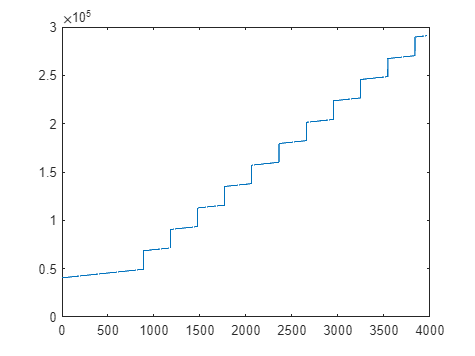

OPF1D2 =     1.0056    0.4096    0.6785
    1.0045    0.4137    0.6785
    1.0045    0.4056    0.6785
    1.0045    0.4056    0.6785
    1.0022    0.4056    0.6768
    1.0033    0.4056    0.6768
    1.0033    0.4056    0.6785
    1.0022    0.3976    0.6785
    1.0022    0.4016    0.6785
    1.0033    0.4016    0.6785


OPF1T2 =        40527
       40537
       40547
       40557
       40567
       40577
       40587
       40597
       40607
       40617


OPF1T3 =     11     0
    21     0
    31     0
    41     0
    51     0
    61     0
    71     0
    81     0
    91     0
   101     0


ShiftsO1 = 1.0e+04 *

         0   -0.0000    0.0528
    0.0001   -0.0000    0.0528
    0.0002   -0.0000    0.0528
    0.0003   -0.0000    0.0528
    0.0004   -0.0000    0.0528
    0.0005   -0.0000    0.0528
    0.0006   -0.0000    0.0528
    0.0007   -0.0000    0.0528
    0.0008   -0.0000    0.0529
    0.0009   -0.0000    0.0529


Bshift1 = 0

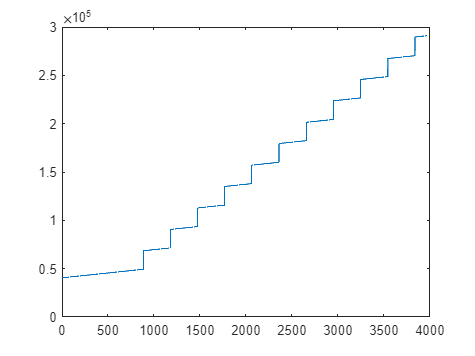

OPF2D2 =     0.5000    0.6026    0.1122
    0.4946    0.5960    0.1122
    0.5000    0.5894    0.1097
    0.4946    0.5894    0.1097
    0.4946    0.5960    0.1097
    0.4946    0.6026    0.1097
    0.4891    0.5960    0.1097
    0.4946    0.6026    0.1097
    0.4891    0.6026    0.1122
    0.4946    0.6093    0.1122


OPF2T2 =        40537
       40547
       40557
       40567
       40577
       40587
       40597
       40607
       40617
       40627


OPF2T3 =     11     0
    21     0
    31     0
    41     0
    51     0
    61     0
    71     0
    81     0
    91     0
   101     0


ShiftsO2 = 1.0e+04 *

         0   -0.0000    0.0529
    0.0001   -0.0000    0.0528
    0.0002   -0.0000    0.0528
    0.0003   -0.0000    0.0529
    0.0004   -0.0000    0.0528
    0.0005   -0.0000    0.0529
    0.0006   -0.0000    0.0529
    0.0007   -0.0000    0.0529
    0.0008   -0.0000    0.0529
    0.0009   -0.0000    0.0531


Bshift2 = 0

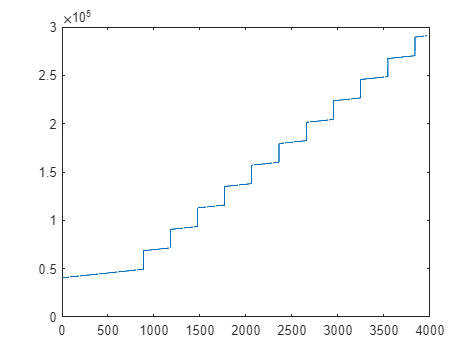

OPF3D2 =     0.4828    0.6708    0.0044
    0.4828    0.6738    0.0029
    0.4828    0.6769    0.0029
    0.4810    0.6800    0.0029
    0.4810    0.6831    0.0044
    0.4774    0.6831    0.0044
    0.4792    0.6892    0.0044
    0.4774    0.6862    0.0058
    0.4792    0.6862    0.0058
    0.4792    0.6892    0.0073


OPF3T2 =        40537
       40547
       40557
       40567
       40577
       40587
       40597
       40607
       40617
       40627


OPF3T3 =     11     0
    21     0
    31     0
    41     0
    51     0
    61     0
    71     0
    81     0
    91     0
   101     0


ShiftsO3 = 1.0e+04 *

         0   -0.0000    0.0531
    0.0001   -0.0000    0.0531
    0.0002   -0.0000    0.0531
    0.0003   -0.0000    0.0531
    0.0004   -0.0000    0.0531
    0.0005   -0.0000    0.0531
    0.0006   -0.0000    0.0531
    0.0007   -0.0000    0.0531
    0.0008   -0.0000    0.0530
    0.0009   -0.0000    0.0530


Bshift3 = 0

allopt = struct with fields:
       fig: [1×1 Figure]
    stsize: 10
       MTC: 'r o'
      OP1C: 'b o'
      OP2C: 'k o'
      OP3C: 'm o'
      xmax: 0
      ymax: 0
         i: 0


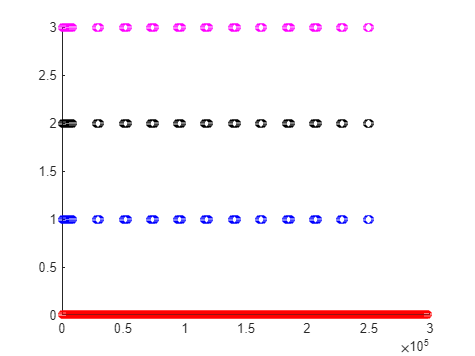

List = 1.0e+04 *

    0.0001    0.0011    0.0001    0.0011    0.0001   -0.0000
    0.0002    0.0012    0.0002    0.0012    0.0002   -0.0000
    0.0003    0.0013    0.0003    0.0013    0.0003   -0.0000
    0.0004    0.0014    0.0004    0.0013    0.0014   -0.0000
    0.0005    0.0015    0.0005    0.0013    0.0015   -0.0000
    0.0006    0.0016    0.0016    0.0013    0.0016   -0.0000
    0.0007    0.0017    0.0017    0.0013    0.0017   -0.0000
    0.0008    0.0018    0.0018    0.0013    0.0018   -0.0000
    0.0009    0.0019    0.0019    0.0013    0.0019   -0.0000
    0.0010    0.0020    0.0020    0.0013    0.0019   -0.0000


retopt = 0.2849

S1 = 20407

S2 = 20412

S3 = 20414


BNLL =

  0×0 empty cell array



ans = 3972

ans = 3972


BNLL =

  0×0 empty cell array



ans = 3972

ans = 3972


BNLL =

  0×0 empty cell array



ans = 3972

ans = 3972

TMPi = 1×5 cell array
    {3972×15 double}    {3972×8 double}    {3972×3 double}    {3972×3 double}    {3972×3 double}


DataSet_Labels =     0.8614    0.5778    0.8706    0.7204    0.6964    0.9754    0.6549    0.7363    0.9599    0.7765    0.7304    0.9873    0.7500    0.7238    0.9964
    0.8614    0.5778    0.8706    0.7204    0.6964    0.9754    0.6549    0.7363    0.9599    0.7765    0.7304    0.9873    0.7500    0.7238    0.9964
    0.8614    0.5778    0.8706    0.7204    0.6964    0.9754    0.6549    0.7363    0.9599    0.7765    0.7304    0.9873    0.7500    0.7238    0.9964
    0.8614    0.5778    0.8706    0.7204    0.6964    0.9754    0.6549    0.7363    0.9599    0.7765    0.7304    0.9873    0.7500    0.7238    0.9964
    0.8614    0.5778    0.8706    0.7204    0.6964    0.9754    0.6549    0.7363    0.9599    0.7765    0.7304    0.9873    0.7500    0.7238    0.9964
    0.8614    0.5778    0.8706    0.7204    0.6964    0.9754    0.6549    0.7363    0.9599    0.7765    0.7304    0.9873    0.7500    0.7238    0.9964
    0.8614    0.5778    0.8706    0.7204    0.6964    0.9754    0.6549    0.7

DataSet_Myo =     1.0000    1.0496    1.0397    1.0164    1.0392    1.0079    1.0159    1.0240
    1.0000    1.0178    1.0015    1.0637    1.0109    1.0003    1.0082    1.0163
    0.9855    1.0090    1.0362    1.1403    1.0455    1.0072    1.0079    1.0233
    0.9910    1.0083    1.0051    1.1190    1.0063    0.9873    1.0010    1.0170
    0.9987    1.0427    1.0132    1.1762    1.0408    1.0105    1.0198    1.0227
    0.9874    1.0036    1.0159    1.0256    0.9945    1.0095    1.0049    1.0113
    0.9841    1.0292    1.0519    1.0270    1.0026    0.9960    1.0000    0.9898
    0.9784    1.0117    1.0407    1.1057    1.0168    0.9921    1.0057    1.0127
    0.9762    0.9888    1.0048    1.0699    0.9996    0.9868    1.0079    1.0240
    0.9825    0.9835    0.9795    1.0345    0.9824    0.9905    1.0079    1.0113


DataSet_Opt =     0.4215    0.6962    0.0641    0.4103    0.6756    0.0130    0.9753    0.3452    0.6469
    0.4213    0.6968    0.0634    0.4100    0.6755    0.0129    0.9751    0.3451    0.6466
    0.4211    0.6975    0.0628    0.4097    0.6754    0.0128    0.9750    0.3449    0.6463
    0.4209    0.6981    0.0622    0.4093    0.6753    0.0127    0.9748    0.3447    0.6460
    0.4207    0.6988    0.0616    0.4090    0.6752    0.0125    0.9747    0.3446    0.6457
    0.4205    0.6994    0.0610    0.4087    0.6751    0.0124    0.9745    0.3444    0.6454
    0.4204    0.7000    0.0604    0.4084    0.6750    0.0123    0.9744    0.3443    0.6451
    0.4202    0.7007    0.0598    0.4081    0.6749    0.0122    0.9742    0.3441    0.6448
    0.4200    0.7013    0.0592    0.4077    0.6748    0.0121    0.9741    0.3440    0.6445
    0.4198    0.7020    0.0586    0.4074    0.6747    0.0120    0.9739    0.3438    0.6442



DSSmin =

     []



minLS = 38

rets =     0.2849   -0.0545


rets =     0.2849   -0.0545


allopt = struct with fields:
       fig: [1×1 Figure]
    stsize: 10
       MTC: 'r o'
      OP1C: 'b o'
      OP2C: 'k o'
      OP3C: 'm o'
      xmax: 297825
      ymax: 10
         i: 1


DSSmin = 38

init = 1

[rets(1, 1), rets(1, 2), allopt, DSSmin, init] = CMO_MeasuremnetOptBreak(measurement, measdir, info, newdirec, allopt, sens_order, init)

sens_order = [1, 2, 4, 5, 3];
for i = 2:size(measurements)
    measurement = measurements{i,2}
    
    [rets(i, 1), rets(i, 2), allopt, minLS, init] = CMO_MeasuremnetOptBreak(measurement, measdir, info, newdirec, allopt, sens_order, init)
    DSSmin = [DSSmin, minLS]
end

allopt.fig

save ResultMat.mat
savefig(allopt.fig,'AllTimes.fig')

[1,3]

Norm = @(x, xmm)( ...
        (x(:, 2:end)-xmm(1,:))./(xmm(2,:)-xmm(1,:)) ...
    );

T = round(info.T);
bias = zeros(1,info.sensors+1);

%newdir = join([newdirec, measurement{1}, '/']);

data = [];
for i = 1:size(measurement{2}, 1)
    data = [data;readmatrix(join([measdir,measurement{2}{i,4}]))];
    display(measurement{2}{i,4})
end
data = data(2:end, :);
starters(1:6) = data(1,[info.compT, info.glvINDt, info.myoINDt, info.op1INDt, info.op2INDt, info.op3INDt]);



guide = data(:, [info.stateIND, info.movementIND, info.compT]);

glv = data(:, [info.glvINDt, info.glvIND]);
myo = data(:, [info.myoINDt, info.myoIND]);
op1 = data(:, [info.op1INDt, info.op1IND]);
op2 = data(:, [info.op2INDt, info.op2IND]);
op3 = data(:, [info.op3INDt, info.op3IND]);

prevTS2 = [guide(1,3), glv(1,1), myo(1,1), op1(1,1), op2(1,1), op3(1,1)];
prevTS4 = prevTS2;
glv(:, 2:end) = Norm(glv, info.glvMM);
myo(:, 2:end) = Norm(myo, info.myoMM);
op1(:, 2:end) = Norm(op1, info.op1MM);
op2(:, 2:end) = Norm(op2, info.op2MM);
op3(:, 2:end) = Norm(op3, info.op3MM);
prevVS = {guide(1,1:2), glv(1,2:end), myo(1, 2:end), op1(1, 2:end), op2(1, 2:end), op3(1,2:end)};

glv = glv(2:end, :);
myo = myo(2:end, :);
op1 = op1(2:end, :);
op2 = op2(2:end, :);
op3 = op3(2:end, :);


guide(:,3) = guide(:,3) - starters(1);
glv(:,1) =  glv(:,1) - starters(2);
myo(:,1) =  myo(:,1) - starters(3);
%difference
prevTS3(1) = prevTS2(1) - starters(1);
prevTS3(2) = prevTS2(2) - starters(2);
prevTS3(3) = prevTS2(3) - starters(3);
prevTS3(4) = prevTS2(4) - starters(4);
prevTS3(5) = prevTS2(5) - starters(5);
prevTS3(6) = prevTS2(6) - starters(6);
prevTS4 = prevTS3;

COMP = [glv(:,1),glv(:,2:end),myo(:,2:end)];

[RS_DC, RS_TC] = CMO_Interp1Part(COMP(:,2:end), COMP(:,1), 1/T, [prevVS{2}, prevVS{3}], prevTS4(2));
RS_TC = RS_TC';
OUglv = [RS_TC, RS_DC(:,1:size(glv, 2)-1)];
OUmyo = [RS_TC, RS_DC(:,size(glv, 2):end)];
EUglv = [RS_TC, CMO_Metric_Euc(OUglv(:,2:end))];
EUmyo = [RS_TC, CMO_Metric_Euc(OUmyo(:,2:end))];

DataSet_Labels = OUglv
DataSet_Myo = OUmyo

EUMdata = CMO_Metric_Euc(DataSet_Labels(:,2:end));
MT = DataSet_Labels(:,1)

[OPF1D2, OPF1T2, OPF1T3, OPF1T4, ShiftsO1, Bshift1] = CMO_OptShiftCorrBest(op1, bias(4), prevTS2(4), prevTS3(4), prevVS{4}, starters(4), MT, T, EUMdata)
[OPF2D2, OPF2T2, OPF2T3, OPF2T4, ShiftsO2, Bshift2] = CMO_OptShiftCorrBest(op2, bias(5), prevTS2(5), prevTS3(5), prevVS{5}, starters(5), MT, T, EUMdata)
[OPF3D2, OPF3T2, OPF3T3, OPF3T4, ShiftsO3, Bshift3] = CMO_OptShiftCorrBest(op3, bias(6), prevTS2(6), prevTS3(6), prevVS{6}, starters(6), MT, T, EUMdata)

close all
%plots
%Optoforces time 
f1 = figure(1)
hold on
xlim([0, max(MT)])
ylim([0, 4])
%title('Optoforce időbélyegek lefedése )
xlabel('idő (ms)')
ax = gca;
ax.YTick      = [0,1,2,3];
ax.YTickLabel = {'Számítógép idő','Optoforce 1', 'Optoforce 2', 'Optoforce 3'}
plot(MT, zeros(length(MT), 1),  'r o')
plot(OPF1T3(:,1), ones(size(OPF1T3, 1), 1), 'b o')
plot(OPF2T3(:,1), ones(size(OPF2T3, 1), 1)*2, 'k o')
plot(OPF3T3(:,1), ones(size(OPF3T3, 1), 1)*3, 'm o')
hold off


%{
allopt.fig
allopt.xmax
allopt.ymax
allopt.MTC
allopt.OP1C
allopt.OP2C
allopt.OP3C
%}



%plots

[List] = CMO_WindowCombSearch(ShiftsO1(:,2), ShiftsO2(:,2), ShiftsO3(:,2), 11)

%plot
f2 = figure(2)
hold on
%title('Optoforce időbélyegek lefedése )
xlabel('OF idő eltolás (11ms ablak) (ms)')
ylabel('Korreláció')
plot(List(:, 1), List(:, 6))
%plot

S1 = List(List(:, 6) == max(List(:, 6)), 3)-1
S2 = List(List(:, 6) == max(List(:, 6)), 4)-1
S3 = List(List(:, 6) == max(List(:, 6)), 5)-1

[SFO1] = CMO_OptShift(op1, bias(4), prevTS2(4), prevTS3(4), prevVS{4}, starters(4), MT, T, EUMdata, S1)
[SFO2] = CMO_OptShift(op2, bias(5), prevTS2(5), prevTS3(5), prevVS{5}, starters(5), MT, T, EUMdata, S2)
[SFO3] = CMO_OptShift(op3, bias(6), prevTS2(6), prevTS3(6), prevVS{6}, starters(6), MT, T, EUMdata, S3)

LOM = SFO1(:, 4) & SFO2(:, 4) & SFO3(:, 4)

DataSet_Opt = [SFO1(:, 1:3), SFO2(:, 1:3), SFO3(:, 1:3)]


size(LOM)
size(DataSet_Labels)

DataSet_Labels = DataSet_Labels(:, 2:end)
DataSet_Labels = DataSet_Labels(:,[1, 2, 3, 5, 6, 7, 9, 10, 11, 13, 14, 15, 17, 18, 19]);
DataSetsLab = CMO_SepByLindex(DataSet_Labels, LOM);

DataSetsMyo = CMO_SepByLindex(DataSet_Myo(:, 2:end), LOM);
DataSetsOpt = CMO_SepByLindex(DataSet_Opt, LOM);

labels_name = 'dataset_labels';
myo_name = 'dataset_myo';
opt_name = 'dataset_opt';

Ldir = join([newdirec, 'labels']);
mkdir(Ldir);

Mdir = join([newdirec, 'myo']);
mkdir(Mdir);

Odir = join([newdirec, 'opt']);
mkdir(Odir);


CMO_WriteList(DataSetsLab, Ldir, labels_name, init)
CMO_WriteList(DataSetsMyo, Mdir, myo_name, init)
CMO_WriteList(DataSetsOpt, Odir, opt_name, init)


%writematrix(guide,join([newdir,'guide/', measurement{2}{1,2}, '_', measurement{2}{1,3},'_gui.txt']) )

function [retopt, retmyo, allopt, DSSmin, init] = CMO_MeasuremnetOptBreak(measurement, measdir, info, newdirec, allopt, sens_order, init)
    if nargin < 7
        sens_order = 1:5;
    end
    if nargin < 8
        init = 0;
    end
    Norm = @(x, xmm)( ...
            (x(:, 2:end)-xmm(1,:))./(xmm(2,:)-xmm(1,:)) ...
        );
    
    T = round(info.T);
    bias = zeros(1,info.sensors+1);
    
    %newdir = join([newdirec, measurement{1}, '/']);
    
    data = [];
    for i = 1:size(measurement, 1)
        data = [data;readmatrix(join([measdir,measurement{i,4}]))];
    end
    data = data(2:end, :)
    starters(1:6) = data(1,[info.compT, info.glvINDt, info.myoINDt, info.op1INDt, info.op2INDt, info.op3INDt])
    
    
    
    guide = data(:, [info.stateIND, info.movementIND, info.compT]);
    
    glv = data(:, [info.glvINDt, info.glvIND]);
    myo = data(:, [info.myoINDt, info.myoIND]);
    op1 = data(:, [info.op1INDt, info.op1IND]);
    op2 = data(:, [info.op2INDt, info.op2IND]);
    op3 = data(:, [info.op3INDt, info.op3IND]);
    
    prevTS2 = [guide(1,3), glv(1,1), myo(1,1), op1(1,1), op2(1,1), op3(1,1)]
    prevTS4 = prevTS2;
    glv(:, 2:end) = Norm(glv, info.glvMM);
    myo(:, 2:end) = Norm(myo, info.myoMM);
    op1(:, 2:end) = Norm(op1, info.op1MM);
    op2(:, 2:end) = Norm(op2, info.op2MM);
    op3(:, 2:end) = Norm(op3, info.op3MM);
    prevVS = {guide(1,1:2), glv(1,2:end), myo(1, 2:end), op1(1, 2:end), op2(1, 2:end), op3(1,2:end)}
    
    glv = glv(2:end, :);
    myo = myo(2:end, :);
    op1 = op1(2:end, :);
    op2 = op2(2:end, :);
    op3 = op3(2:end, :);
    
    
    guide(:,3) = guide(:,3) - starters(1);
    glv(:,1) =  glv(:,1) - starters(2);
    myo(:,1) =  myo(:,1) - starters(3);
    %difference
    prevTS3(1) = prevTS2(1) - starters(1);
    prevTS3(2) = prevTS2(2) - starters(2);
    prevTS3(3) = prevTS2(3) - starters(3);
    prevTS3(4) = prevTS2(4) - starters(4);
    prevTS3(5) = prevTS2(5) - starters(5);
    prevTS3(6) = prevTS2(6) - starters(6);
    prevTS3
    prevTS4 = prevTS3;
    
    COMP = [glv(:,1),glv(:,2:end),myo(:,2:end)];
    
    [RS_DC, RS_TC] = CMO_Interp1Part(COMP(:,2:end), COMP(:,1), 1/T, [prevVS{2}, prevVS{3}], prevTS4(2));
    RS_TC = RS_TC';
    OUglv = [RS_TC, RS_DC(:,1:size(glv, 2)-1)];
    OUmyo = [RS_TC, RS_DC(:,size(glv, 2):end)];
    EUglv = [RS_TC, CMO_Metric_Euc(OUglv(:,2:end))];
    EUmyo = [RS_TC, CMO_Metric_Euc(OUmyo(:,2:end))];

    retmyo = corrcoef(EUmyo(:, 2), EUglv(:, 2))
    retmyo = retmyo(1,2)
    
    DataSet_Labels = OUglv;
    DataSet_Myo = OUmyo;
    
    EUMdata = CMO_Metric_Euc(DataSet_Labels(:,2:end));
    MT = DataSet_Labels(:,1)
    
    [OPF1D2, OPF1T2, OPF1T3, ShiftsO1, Bshift1] = CMO_OptShiftCorrBest(op1, bias(4), prevTS2(4), prevTS3(4), prevVS{4}, starters(4), MT, T, EUMdata)
    [OPF2D2, OPF2T2, OPF2T3, ShiftsO2, Bshift2] = CMO_OptShiftCorrBest(op2, bias(5), prevTS2(5), prevTS3(5), prevVS{5}, starters(5), MT, T, EUMdata)
    [OPF3D2, OPF3T2, OPF3T3, ShiftsO3, Bshift3] = CMO_OptShiftCorrBest(op3, bias(6), prevTS2(6), prevTS3(6), prevVS{6}, starters(6), MT, T, EUMdata)
    

    %allopt.fig
    figure
    hold on
    
    title('Optoforce időbélyegek lefedése'  )
    xlabel('idő (ms)')
    ax = gca;
    ax.YTick      = [0,1,2,3];
    ax.YTickLabel = {'Számítógép idő','Optoforce 1', 'Optoforce 2', 'Optoforce 3'}

    allopt.stsize = 10
    allopt.MTC = 'r o';
    allopt.OP1C = 'b o';
    allopt.OP2C = 'k o';
    allopt.OP3C = 'm o';

    allopt.xmax = max([allopt.xmax, max(MT)]);
    allopt.ymax = allopt.ymax +allopt.stsize;
    
    plot(MT, zeros(length(MT), 1) + allopt.i *allopt.stsize,  allopt.MTC)
    plot(OPF1T3(:,1), ones(size(OPF1T3, 1), 1) + allopt.i *allopt.stsize, allopt.OP1C)
    plot(OPF2T3(:,1), ones(size(OPF2T3, 1), 1)*2 + allopt.i *allopt.stsize, allopt.OP2C)
    plot(OPF3T3(:,1), ones(size(OPF3T3, 1), 1)*3 + allopt.i *allopt.stsize, allopt.OP3C)
    allopt.i =  allopt.i +1;
    hold off
    %}
    
    [List] = CMO_WindowCombSearch(ShiftsO1(:,2), ShiftsO2(:,2), ShiftsO3(:,2), 11)
    retopt = max(List(:, 6))
    S1 = List(List(:, 6) == retopt, 3)-1;
    S1 = S1(1,1)
    S2 = List(List(:, 6) == retopt, 4)-1;
    S2 = S2(1,1)
    S3 = List(List(:, 6) == retopt, 5)-1;
    S3 = S3(1,1)
    
    [SFO1] = CMO_OptShift(op1, bias(4), prevTS2(4), prevTS3(4), prevVS{4}, starters(4), MT, T, EUMdata, S1);
    [SFO2] = CMO_OptShift(op2, bias(5), prevTS2(5), prevTS3(5), prevVS{5}, starters(5), MT, T, EUMdata, S2);
    [SFO3] = CMO_OptShift(op3, bias(6), prevTS2(6), prevTS3(6), prevVS{6}, starters(6), MT, T, EUMdata, S3);
    
    LOM = [SFO1(:, 4) & SFO2(:, 4) & SFO3(:, 4)];

    DataSet_Opt = [SFO1(:, 1:3), SFO2(:, 1:3), SFO3(:, 1:3)];
    DataSet_Labels = DataSet_Labels(:, 2:end);
    DataSet_Labels = DataSet_Labels(:,[1, 2, 3, 5, 6, 7, 9, 10, 11, 13, 14, 15, 17, 18, 19]);
    DataSet_Myo = DataSet_Myo(:, 2:end);

    TMPi = {DataSet_Labels, DataSet_Myo, SFO1(:, 1:3), SFO2(:, 1:3), SFO3(:, 1:3)}
    DataSet_Labels = TMPi{sens_order(1)}
    DataSet_Myo = TMPi{sens_order(2)}
    DataSet_Opt = [TMPi{sens_order(3)}, TMPi{sens_order(4)}, TMPi{sens_order(5)}]

    DataSetsLab = CMO_SepByLindex(DataSet_Labels, LOM);
    
    DataSetsMyo = CMO_SepByLindex(DataSet_Myo, LOM);
    DataSetsOpt = CMO_SepByLindex(DataSet_Opt, LOM);
    
    DSSmin = []
    for i = 1:size(DataSetsMyo, 1)
            DSSmin(i) = size(DataSetsMyo{i}, 1);
    end
    minLS = min(DSSmin)
    
    labels_name = 'dataset_labels';
    myo_name = 'dataset_myo';
    opt_name = 'dataset_opt';
    
    Ldir = join([newdirec, 'labels']);
    mkdir(Ldir);
    
    Mdir = join([newdirec, 'myo']);
    mkdir(Mdir);
    
    Odir = join([newdirec, 'opt']);
    mkdir(Odir);
    
    CMO_WriteList(DataSetsLab, Ldir, labels_name, init)
    CMO_WriteList(DataSetsMyo, Mdir, myo_name, init)
    CMO_WriteList(DataSetsOpt, Odir, opt_name, init)
    init = init + size(DataSetsMyo, 1);
end